Time range:

tmax = 500;

Initial values for S, I and R:

S0 = 1;
I0 = 1.27e-6;
R0 = 0;

Birth rate and death rate parameters:

b = 1/2;
k = 1/3;

Predict population dynamics for SIR model with Euler's method:

[S, I, R] = SIRmodel(tmax, S0, I0, R0, b, k)

S =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9996    0.9996    0.9995    0.9994    0.9993    0.9992    0.9990    0.9989    0.9987    0.9985    0.9982    0.9979    0.9975    0.9971    0.9967    0.9961    0.9955    0.9947    0.9938    0.9928


I =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0010    0.0011    0.0013    0.0015    0.0018    0.0020    0.0024


R =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0005    0.0006    0.0006    0.0008    0.0009    0.0010    0.0012    0.0014    0.0016    0.0019    0.0022    0.0026    0.0030    0.0035    0.0041    0.0048


Plot S, I and R vs time:

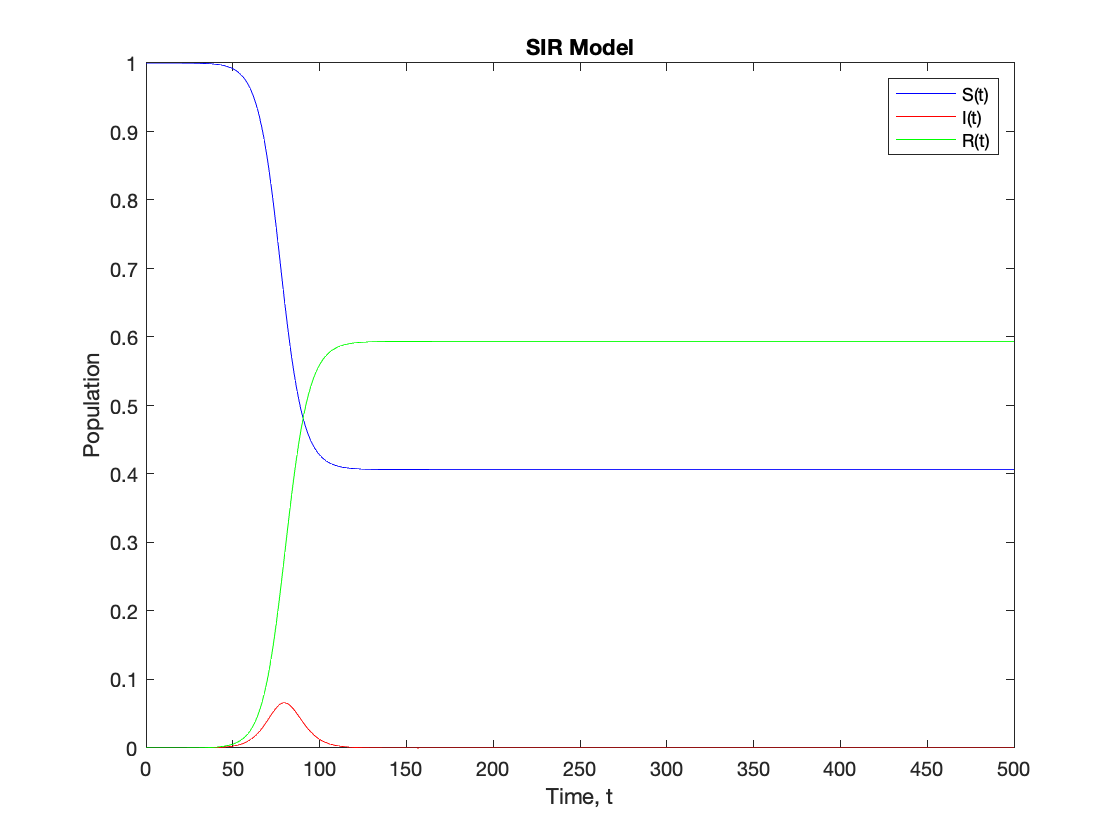

plot(0:tmax, S, 'b')

hold on

plot(0:tmax, I, 'r')
plot(0:tmax, R, 'g')

title('SIR Model')
legend('S(t)', 'I(t)', 'R(t)')

xlabel('Time, t')
ylabel('Population')

% xlim([0, 40])

hold off

This function defines S(t), I(t) and R(t) with the Euler's method.

function [S,I,R] = SIRmodel(tmax, S0, I0, R0, b, k)

    S = zeros(1, tmax);
    I = zeros(1, tmax);
    R = zeros(1, tmax);
    
    S(1) = S0;
    I(1) = I0;
    R(1) = R0;
    
    T(1) = 0;

    Delta_t = 1;

    for n = 1:tmax
    
        T(n+1) = T(n) + Delta_t;

        S(n+1) = S(n) - b * S(n) * I(n) * Delta_t;
        I(n+1) = I(n) + (b * S(n) *I(n) - k * I(n)) * Delta_t;
        R(n+1) = R(n) + k * I(n) * Delta_t;
    
    end

end